# Examen RA3L "intro Matlab"      6 novembre 2024  08h30 -> 10h00 (1h30) 

% Nom :  Adda                                          /8
% Prénom : SAB     
% Matricule :   

## Feuilles d'automne

Des scientifiques aimeraient étudier la forme des feuilles qu'ils retrouvent en sortie de leur laboratoire chaque automne. 

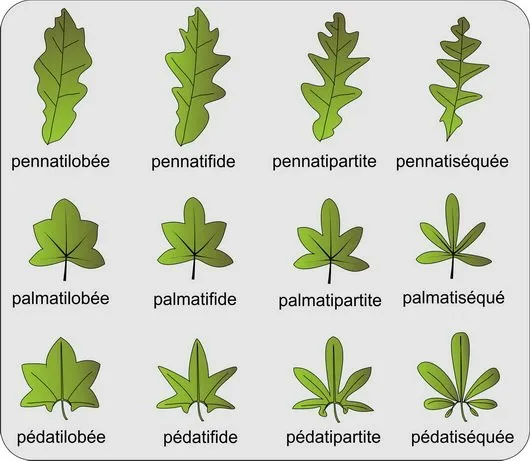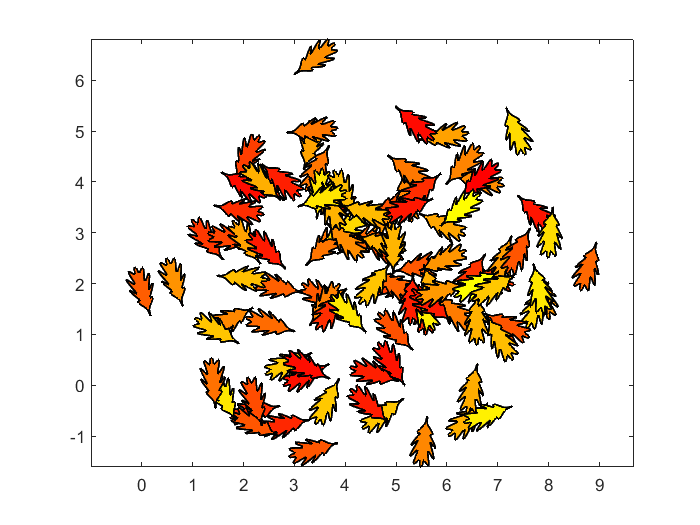

Ils découvrent les travaux d'un ancien collègue qui avait déjà mesuré une feuille et avait renseigné les résultats dans un fichier (Feuille.mat). Répondre aux questions ci-dessous afin d'aider ces scientifiques. 

**1) Récupérer les données du fichier "Feuille.mat" fourni.** Ce fichier contient les vecteurs suivants :

- 'x' : les abscisses de la forme de la feuille étudiée

- 'y' : les ordonnées de la forme de la feuille étudiée

- Les coordonnées x et y sont des fonctions paramétriques d'un vecteur 'r', également fourni dans le fichier .mat.

Afficher les données sous forme d'un graphe présentant les ordonnées en fonction des abscisses pour afficher la feuille. 

*(1,5 points) : *

Résultat attendu :

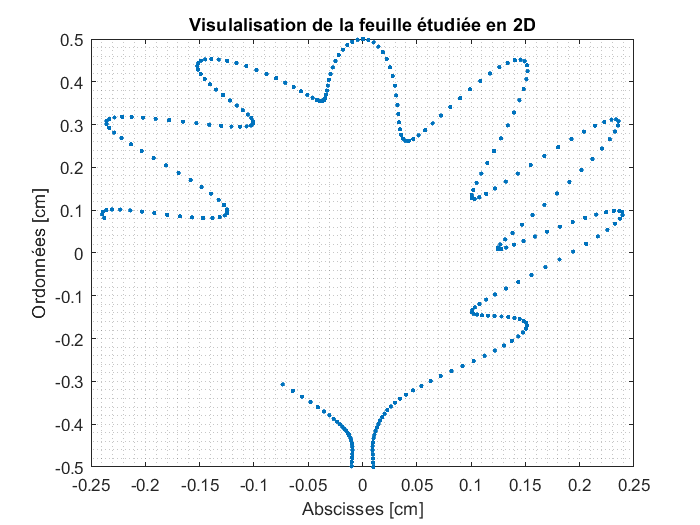

clf;
clear all;
close all;
load('feuille.mat');


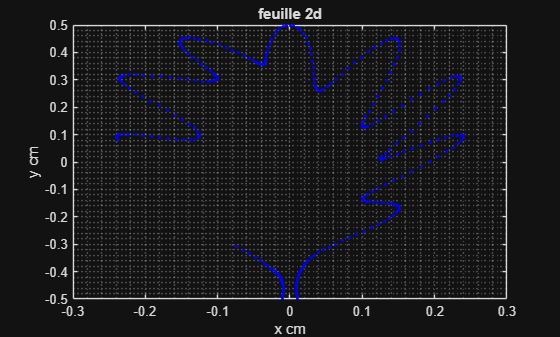

plot(x,y,'.b')
grid minor
xlabel('x cm')
ylabel('y cm')
title('feuille 2d')

2) Les coordonées x et y de la feuille étudiée sont des fonctions du paramètre "r" : 


$$x=F_x \left(r\right)$$



$$y=F_y \left(r\right)=\sin \left(a\;r\right)\left(1-\frac{\sin^2 \left(10r\right)}{5}\left(0,5+\sin^2 \left(b\;r\right)\right)\right)-0,5$$


On s'intéressera ici uniquement aux coordonnées en y. Dans un premier temps, on voudrait tester la fonction $y=F_y \left(r\right)$ pour certaines valeurs de a et de b. Pour cela :

- Créer une fonction "vecteur_y" qui prend comme entrées : la variable r et les paramètres a & b

- Implémenter une boucle permettant de tester et d'afficher la fonction pour 3 valeurs de paramètres a & b, à savoir :

- a = 1 et b = 0,5

- a = 1 et b = 1

- a = 1 et b = 1,5

*(2 points)*

Résultat attendu :

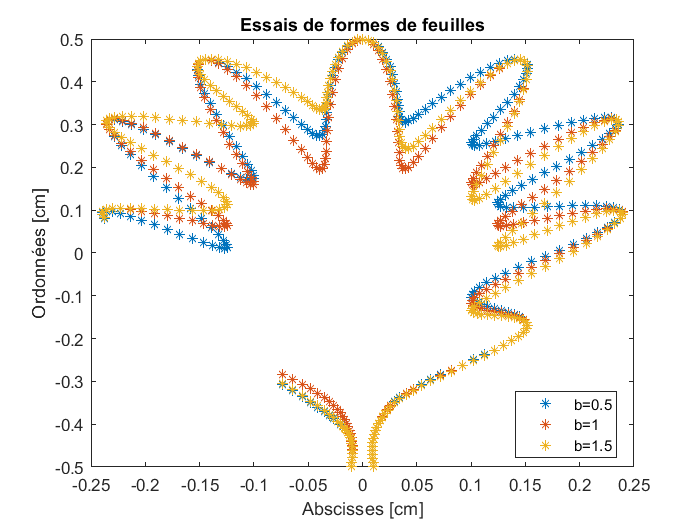

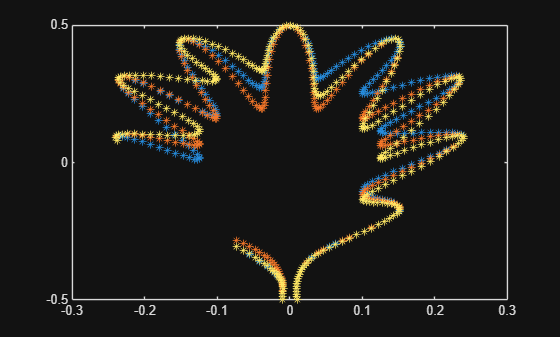

clf;
vecteur_y=@(p,r) sin(p(1).*r).*(1-sin(10.*r).^2/5.*(0.5+sin(p(2).*r).^2))-0.5;
f=[1 0.5;1 1;1 1.5];
for i=1:3
    p=f(i,:);
    plot(x,vecteur_y(p,r),'*')
    hold on
end

3) Sur base des courbes obtenues précédemment, ajuster les paramètres a & b de la fonction $y=F_y \left(r\right)$ ci-dessus, de manière à trouver la courbe **qui passe au plus près des points donnés (au sens des moindres carrés).**

*(1,5 points)*

cost1=@(p) norm(y-vecteur_y(p,r));
p0=[1 1];
min1=fminsearch(cost1,p0);

4) Une partie des données de départ a disparu. Reconstruire la partie manquante (correspondant aux valeurs de r entre 2,53 et 2,90 sur 50 points) en : 

- interpolant via la méthode des "Splines" pour obtenir les données en x (variable x_new)

- réutilisant la fonction "vecteur_y" implémentée et ajustée précédemment (variable y_new)

*(2,5 points)*

Résultat attendu :

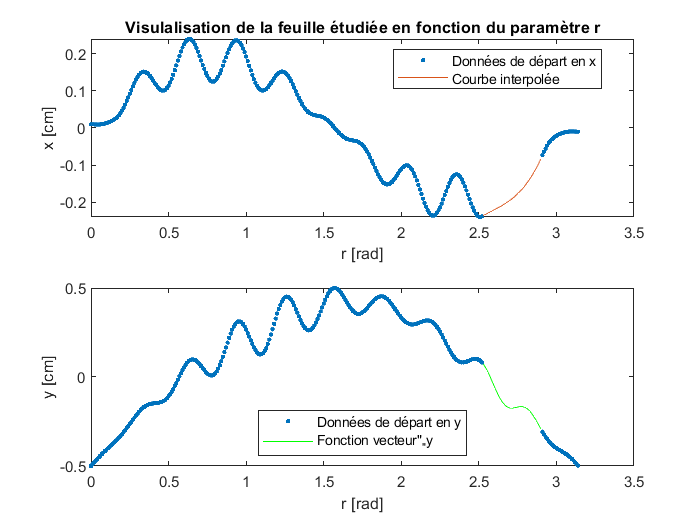

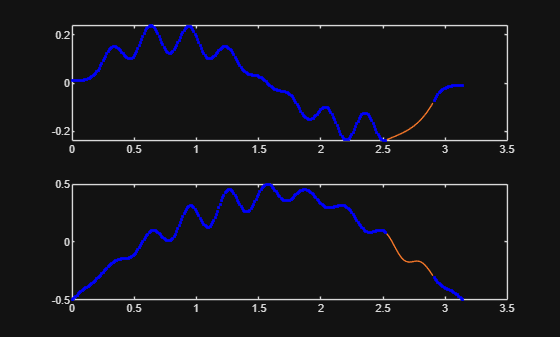

rmank=linspace(2.53,2.9,50);
x_new=interp1(r,x,rmank,'spline');
y_new=vecteur_y(min1,rmank);%rf=[r rmank];[rf,ord]=sort(rf);yf=[y y_new];xf=[x x_new];yf=yf(ord);xf=xf(ord);

subplot(2,1,1)
plot(r,x,'.b',rmank,x_new)

subplot(2,1,2)
plot(r,y,'.b',rmank,y_new)

5) Enfin, afficher l'ensemble de vos résultats en traçant sur le même graphe :

- les données de départ sous forme de points bleus ('.b');

- les données reconstruites au point précédent en vert ('g') ;

*(0,5 points)*

Résultat attendu :

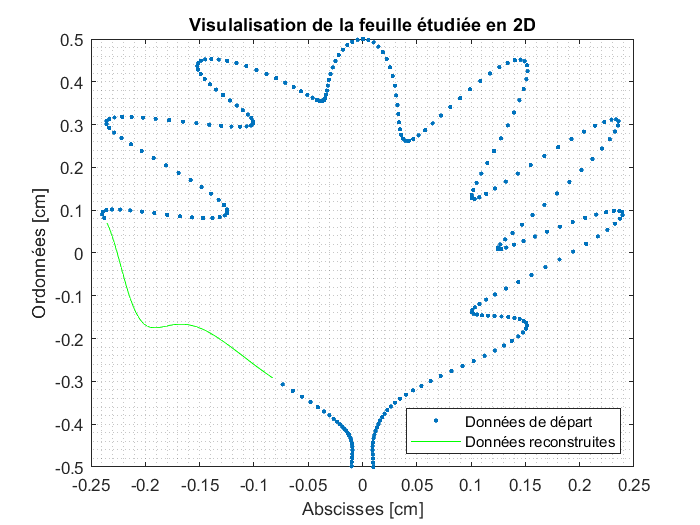

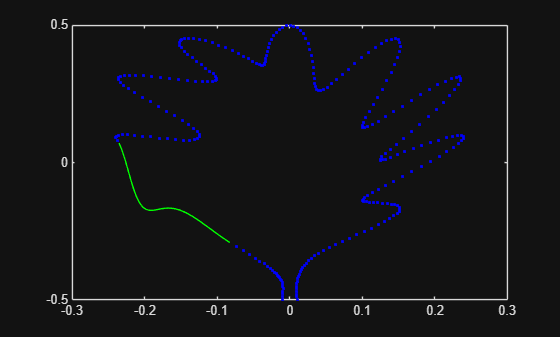

clf;
plot(x,y,'.b',x_new,y_new,'g');